## Setup the Virtual Simulation Environment

[**Instructions to setup RoboCup ARM provided virtual machine**](https://drive.google.com/file/d/1w9tBy3DKmZBKEfOqOFUXcT8hcQig6sNS/view)** (Appendix A)**

Follow the instructions above to setup the MathWorks provided Virtual Machine in your computer.

Find and open one of the environments for the RoboCup ARM Challenge. Note that there is more than on environment provided to ilustrate how objects in the environments are subject to changing positions and orientations based on the challenge instructions. 

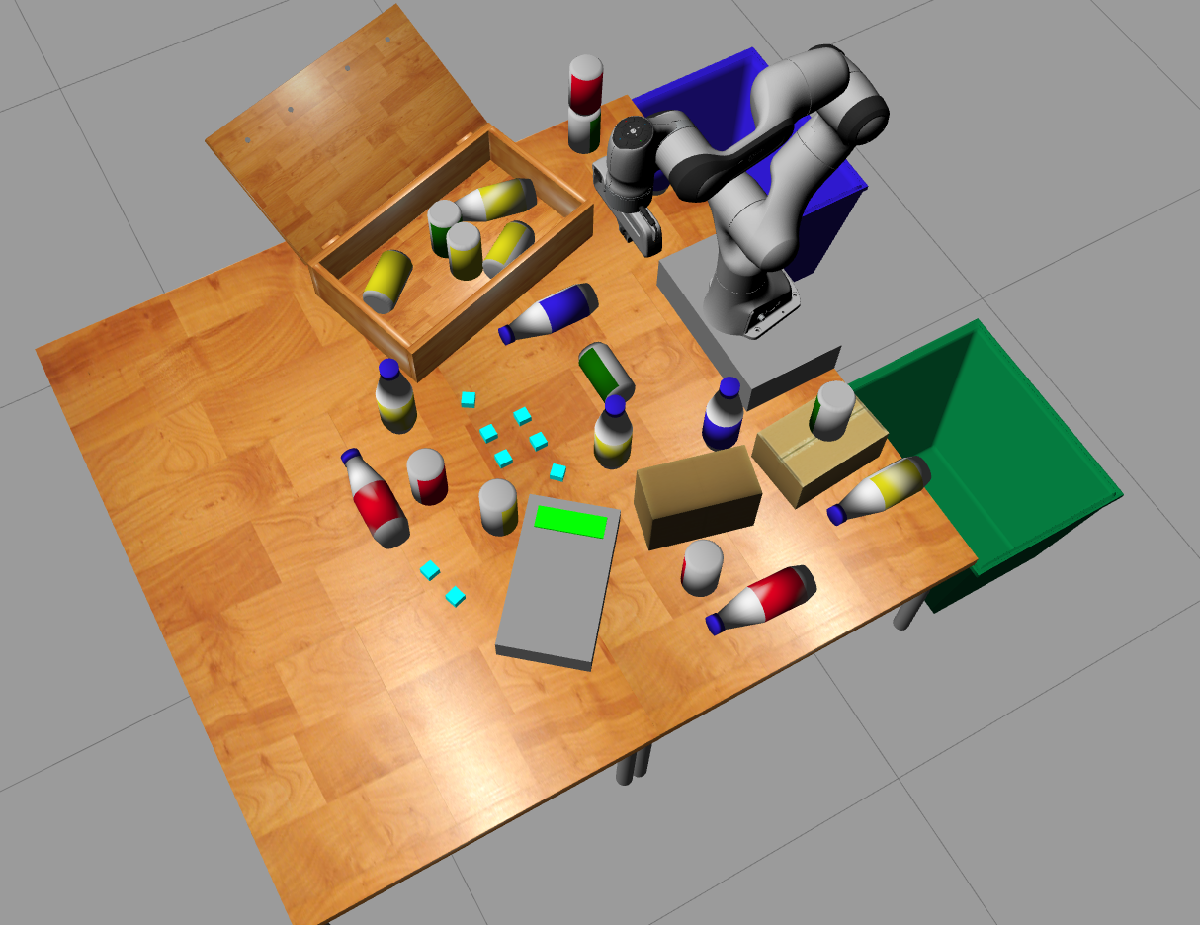

#### Connect MATLAB to Gazebo using the ROS Toolbox

Start a ROS node from MATLAB to interact with the Gazebo environment. For more information on interaction with the ROS ecosystem from MATLAB visit [Getting Started with ROS Toolbox](https://www.mathworks.com/help/ros/getting-started-with-ros-toolbox.html).

If you are having trouble with this step, or if you are waiting a long time for the nodes to communicate, try using the commented code in line 4. The IP address to be specified is the wireless network adapter address.

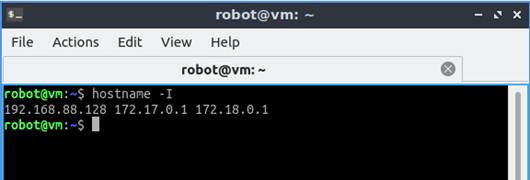

rosIP = "localhost"; % Change IP address!!    % IP address of ROS enabled machine  
rosshutdown; % shut down existing connection to ROS

Shutting down global node /matlab_global_node_69740 with NodeURI http://rdp-Altos-P10-F8:41511/ and MasterURI http://localhost:11311.


rosinit(rosIP,11311);

Initializing global node /matlab_global_node_97518 with NodeURI http://rdp-Altos-P10-F8:41273/ and MasterURI http://localhost:11311.


% rosinit(rosIP,'NodeHost','192.168.68.120') % Try specifying node host IP in case that there are multiple network adapters

## Initialize Robot and Start Simulator

#### Set initial robot configuration

setInitialConfig_franka; % DO NOT MODIFY

#### Unpause GAZEBO physics.

Unpausing the Gazebo simulation is necessary to make sure the environment physics are active.

physicsClient = rossvcclient('gazebo/unpause_physics'); %unpause physics
physicsResp = call(physicsClient,'Timeout',3); %send default message

## Control Gripper Using ROS Action Client

[gripAct,gripGoal] = rosactionclient('/franka_gripper/gripper_action');
gripperCommand = rosmessage(gripAct);

gripperCommand.Command.Position = 2.915; %0 is fully closed, 4 is fully open
gripperCommand.Command.MaxEffort = 50; %N
gripperCommand.Command.Position = gripperCommand.Command.Position / 100;
gripGoal.Command = gripperCommand.Command;
waitForServer(gripAct); % Can use this function if concerned with missed
% goals but generally it should work correctly.
sendGoal(gripAct,gripGoal)

## Control Gripper Position using ROS Action Client

#### Setup ROS message and publisher for Joint Control

jointMess = rosmessage("geometry_msgs/PoseStamped");
jointPub = rospublisher("/cartesian_impedance_example_controller/equilibrium_pose");

#### Define Gripper Pose

This section defines the desired gripper location and orientation using a homogeneous transformation. [Learn more about homogeneous transform here.](https://www.mathworks.com/help/robotics/coordinate-system-transformations.html)

To reset pose to approximate initial configuration, set the gripper location to [0.35, 0.0001, 0.5] and orientation to [-pi. -0.01,0]

gripperX = 0.33;
gripperY = 0.08;
gripperZ = 0.85;
gripperTranslation = [gripperX gripperY gripperZ];
gripperRotationX = -pi; % radians
gripperRotationY = -0.01; % radians
gripperRotationZ = 0; % radians

jointMess.Pose.Position.X = gripperX;
jointMess.Pose.Position.Y = gripperY;
jointMess.Pose.Position.Z = gripperZ;
quat = angle2quat(gripperRotationX, gripperRotationY, gripperRotationZ, "XYZ");
jointMess.Pose.Orientation.W = quat(1);
jointMess.Pose.Orientation.X = quat(2);
jointMess.Pose.Orientation.Y = quat(3);
jointMess.Pose.Orientation.Z = quat(4);
send(jointPub,jointMess);

## **Effective use of RGB camera**

Data processed from the depth camera leads to successful classification of at least one bottle or can.

### Using a YoloV2 model pre-trained on two classes of objects (bottle, can)

disp('*-----Object Detection and Classification-----*')

*-----Object Detection and Classification-----*



% Getting Yolov2 model
% Load deep learning model for object detection
temp = load('exampleHelperYolo2DetectorROSGazebo.mat');
DetectorModel = temp.detectorYolo2;

% Detect parts
% This function detects parts using a pre-trained deep learning model.

% Read image from simulated Gazebo camera
rgbImg = getRGBImage

Getting RGB Image


rgbImg = 480×640×3 uint8 array
rgbImg(:,:,1) =

   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   205   224   225   224   223   223   222   221   220   219   219   218   218   217   217   217   217   217   216   215   212   209   207   205   205   205   204   204   204   203   203   202   203   204   204   205   205   205   163    38    40    42    46    49    49    55    49    50    58    56    49    62    54    58    56    53    57    52    58    63    55    60    59    58    57    56    55    53    53    61    55    51    56    51    57    52    54    56    49    51    50    52    47    

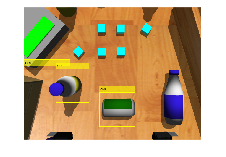


% Detect parts and show labels
[bboxes,~,labels] = detect(DetectorModel,rgbImg);
if ~isempty(labels)
    labeledImg = insertObjectAnnotation(rgbImg,'Rectangle',bboxes,cellstr(labels));
    imshow(labeledImg);            
end

### Detect Objects Using Pretrained YOLO v2 Object Detector

name = "tiny-yolov2-coco";
% Create YOLO v2 object detector by using the pretrained YOLO v2 network.
detector = yolov2ObjectDetector(name);
% Display and inspect the properties of the YOLO v2 object detector.matlab:helpPopup yolov2ObjectDetector
disp(detector)

  yolov2ObjectDetector with properties:

            ModelName: 'tiny-yolov2-coco'
              Network: [1×1 DAGNetwork]
    TrainingImageSize: [416 416]
          AnchorBoxes: [5×2 double]
           ClassNames: [person    bicycle    car    motorbike    aeroplane    bus    train    truck    boat    …    ]



% Read image from simulated Gazebo camera
img = getRGBImage

Getting RGB Image


img = 480×640×3 uint8 array
img(:,:,1) =

   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   205   224   225   224   223   223   222   221   220   219   218   218   218   217   217   217   217   217   216   215   212   209   207   205   205   205   204   204   204   203   203   202   203   204   204   205   205   205   162    38    40    42    46    49    48    54    49    50    61    56    49    62    54    58    56    53    57    52    58    63    55    60    59    58    57    56    54    53    53    61    55    51    56    51    57    51    54    56    49    51    50    51    47    49    

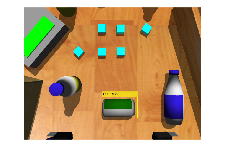

% Detect objects in image by using the pretrained YOLO v2 object detector.
[bboxes,scores,labels] = detect(detector,img);
% Display the detection results.
detectedImg = insertObjectAnnotation(img,"Rectangle",bboxes,labels);
figure
imshow(detectedImg)

## Testing

gripperGoal(3.3, gripAct, gripGoal, gripperCommand)

% use this to calculate and copy pase configurations
pose=getCurrentRobotJConfig;
disp(pose)

## Pick-Place in Static Region

setInitialConfig_franka; % DO NOT MODIFY
jointMess = rosmessage("geometry_msgs/PoseStamped");
jointPub = rospublisher("/cartesian_impedance_example_controller/equilibrium_pose");
pause(2);
[gripAct,gripGoal] = rosactionclient('/franka_gripper/gripper_action');
gripperCommand = rosmessage(gripAct);

### Red Horizontal Bottle

% Pre-defined poses
poses = {[0.31, 0.64, 0.1]};
% Pre-defined configurations w.r.t to Pre-defined poses
goalConfigStaticArray={[1.0178    0.7159    0.1081   -1.6379   -0.0520    2.4146    1.8929]};
% Execute
goToGoal(poses, goalConfigStaticArray, jointPub, jointMess)

Waiting until robot reaches the desired configuration
Goal 1 Achieved




gripperGoal(3.9, gripAct, gripGoal, gripperCommand)



% Pre-defined poses
poses = {[0.31, 0.64, -0.07]};
% Pre-defined configurations w.r.t to Pre-defined poses
goalConfigStaticArray={[1.1033    1.0620    0.0129   -1.4944    0.0365    2.6233    1.8386]};
% Execute
goToGoal(poses, goalConfigStaticArray, jointPub, jointMess)

Waiting until robot reaches the desired configuration
Goal 1 Achieved




gripperGoal(3.3, gripAct, gripGoal, gripperCommand)


% Pre-defined poses
poses = {[0.31, 0.64, 0.1]};
% Pre-defined configurations w.r.t to Pre-defined poses
goalConfigStaticArray={[1.0178    0.7159    0.1081   -1.6379   -0.0520    2.4146    1.8929]};
% Execute
goToGoal(poses, goalConfigStaticArray, jointPub, jointMess)

Waiting until robot reaches the desired configuration
Goal 1 Achieved



setInitialConfig_franka;


% Pre-defined poses
poses = {[-0.4, -0.5, 0.4]}; 
% Pre-defined configurations w.r.t to Pre-defined poses
goalConfigStaticArray={[-0.2114   -1.1348   -1.3451   -1.6423   -1.1436    1.4808   -0.7985]};
% Execute
goToGoal(poses, goalConfigStaticArray, jointPub, jointMess)

Waiting until robot reaches the desired configuration
Goal 1 Achieved



gripperGoal(3.9, gripAct, gripGoal, gripperCommand)

setInitialConfig_franka;

function goToGoal(poses, goalConfigStaticArray, jointPub, jointMess)
    % Iterate over the array of arrays
    for i = 1:numel(poses)
        gripperX = poses{i}(1);
        gripperY = poses{i}(2);
        gripperZ = poses{i}(3);
        gripperTranslation = [gripperX gripperY gripperZ];
        gripperRotationX = -pi; % radians
        gripperRotationY = -0.01; % radians
        gripperRotationZ = 0; % radians
        
        jointMess.Pose.Position.X = gripperX;
        jointMess.Pose.Position.Y = gripperY;
        jointMess.Pose.Position.Z = gripperZ;
        quat = angle2quat(gripperRotationX, gripperRotationY, gripperRotationZ, "XYZ");
        jointMess.Pose.Orientation.W = quat(1);
        jointMess.Pose.Orientation.X = quat(2);
        jointMess.Pose.Orientation.Y = quat(3);
        jointMess.Pose.Orientation.Z = quat(4);
        send(jointPub,jointMess);
    
        % Wait until the robot reaches destination
        pause(1.0);        % this pause is needed to start asking for movement status
        isAway = true;
        disp('Waiting until robot reaches the desired configuration');
        while isAway
            isAway = checkTargetAchieved(goalConfigStaticArray{i});
            pause(1);
        end
        fprintf('Goal %d Achieved',i);
    end
end

function gripperGoal(position, gripAct, gripGoal, gripperCommand)
    gripperCommand.Command.Position = position; %0 is fully closed, 4 is fully open
    gripperCommand.Command.MaxEffort = 20; %N
    gripperCommand.Command.Position = gripperCommand.Command.Position / 100;
    gripGoal.Command = gripperCommand.Command;
    waitForServer(gripAct); % Can use this function if concerned with missed
    % goals but generally it should work correctly.
    sendGoal(gripAct,gripGoal)
    pause(5)
end

## **Function Definitions**

function JConfig = getCurrentRobotJConfig
    jMsg = receive(rossubscriber('/joint_states'));
    JConfig =  jMsg.Position(1:7)';
end

% Receive Camera Image Using ROS Subscriber
function rgbImg = getRGBImage
    disp("Getting RGB Image")
    rgbImgSub = rossubscriber("/camera/rgb/image_raw","sensor_msgs/Image","DataFormat","struct");
    curImage = receive(rgbImgSub,3);
    pause(1)
    rgbImg = rosReadImage(rgbImgSub.LatestMessage); 
end

% Receive Depth Image Using ROS Subscriber
function depthImg = getDepthImage
    disp("Getting Depth Image")
    rgbDptSub = rossubscriber('/camera/depth/image_raw');
    curDepth = receive(rgbDptSub,3);
    depthImg = readImage(rgbDptSub.LatestMessage); 
end

% Check if target achieved
function isAway = checkTargetAchieved(goalConfig)
    isAway = true;
    jointCurrent=(getCurrentRobotJConfig);
    if all(abs((jointCurrent-(goalConfig)))<0.05)     
        isAway=false; % goal achieved       
    end           
end